将文本渲染为二值图像

二值图像是由逻辑值true和false排列成的逻辑矩阵。此函数将输入文本渲染成逻辑矩阵，文本所在的位置为true，空白处为false。

本函数调用内置insertText实现。

## 语法

## 示例

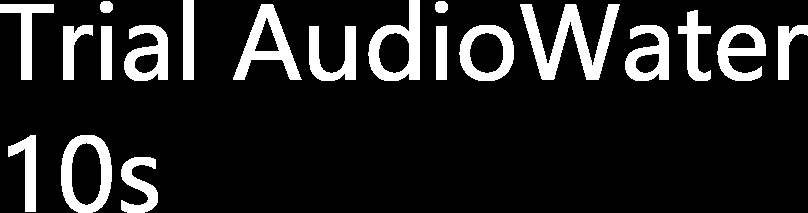

## 输入参数

Text(1,:)char，要渲染的文本

FontSize(1,1)，字体大小。对于单个方块汉字，字体大小为n意味着输出矩阵尺寸大约为n×n，对半宽字符则大约为n×(n/2)。具体大小根据字体会有不同，请勿对此做出任何假设。

Font(1,1)string="Microsoft YaHei"，要渲染的字体。可用listTrueTypeFonts查看所有可用的字体。

## 返回值

Mask(:,:)logical，渲染出的二值图像，可以使用imshow查看、imwrite写出为BMP文件

**See also** [listTrueTypeFonts](matlab:doc listTrueTypeFonts) [insertText](matlab:doc insertText) [imshow](matlab:doc imshow) [imwrite](matlab:doc imwrite)

function Mask = TextMask(Text,FontSize,Font)
arguments
	Text(1,:)char
	FontSize
	Font='Microsoft YaHei'
end
Mask=insertText(zeros(FontSize*2*(sum(Text==newline)+1),FontSize*(strlength(Text)+1),3,'uint8'),[0,0],Text,FontSize=FontSize,Font=Font,TextColor=[255,0,0],BoxColor=[0,255,0]);
[Ys,Xs]=find(Mask(:,:,1));
Mask=logical(Mask(min(Ys):max(Ys),min(Xs):max(Xs),1));